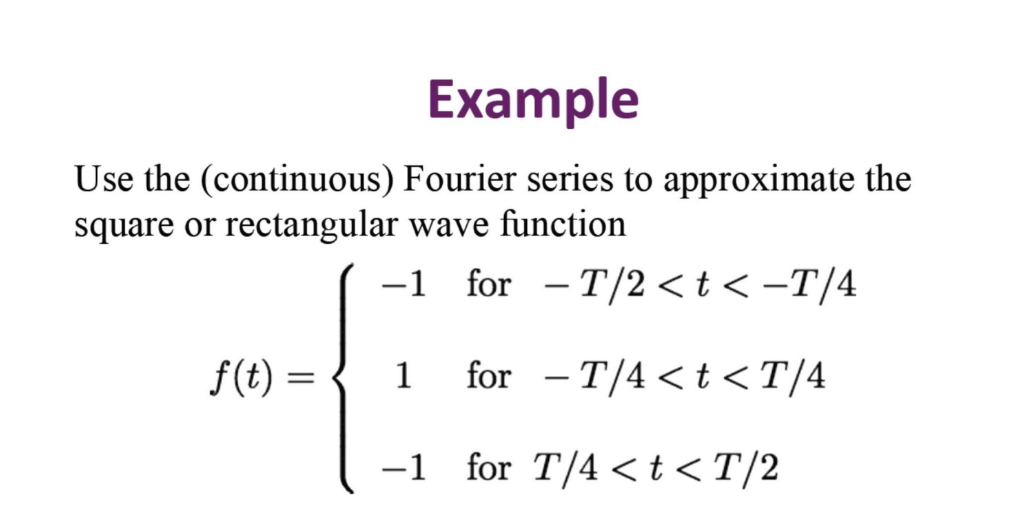

clear
clc
syms t n T;
f1 = -1; f2 = 1; f3 = -1;
a0 = eval((1/t)*(int(f1,t,[-T/2 -T/4])+int(f2,t,[-T/4 T/4])+int(f3,t,[T/4 T/2])))

a0 = 0

assume(n,"integer")
w = 2*pi/T

$$w = \frac{2\,\pi }{T}$$

ans = simplify((2/T)*(int(f1*cos(n*w*t),t,[-T/2 -T/4])+int(f2*cos(n*w*t),t,[-T/4 T/4])+int(f3*cos(n*w*t),t,[T/4 T/2])));

**Define period T**

T = 2*pi;
an = eval((2/T)*(int(f1*cos(n*w*t),t,[-T/2 -T/4])+int(f2*cos(n*w*t),t,[-T/4 T/4])+int(f3*cos(n*w*t),t,[T/4 T/2])));
bn = eval((2/T)*(int(f1*sin(n*w*t),t,[-T/2 -T/4])+int(f2*sin(n*w*t),t,[-T/4 T/4])+int(f3*sin(n*w*t),t,[T/4 T/2])))

bn = 0

w = 2*pi/T;

**number of harmonics**

harm = 10;

**Plot graph**

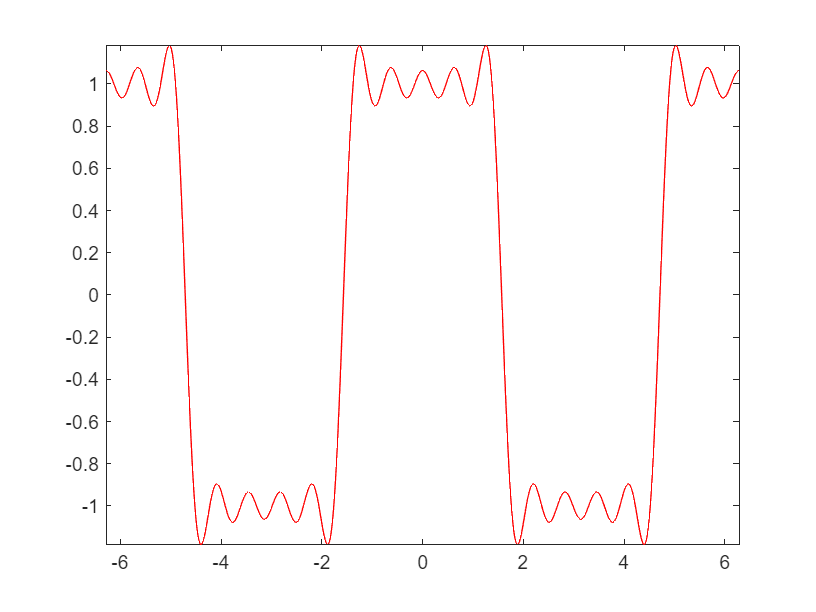

f0 = an*cos(n*w*t)+bn*sin(n*w*t);
fx = a0+symsum(f0,n,1,harm);
fplot(fx,[-2*pi 2*pi],'r')